# Modelagem e Controle de Conversor Boost

**Universidade Tecnológica Federal do Paraná (UTFPR)   **

**Disciplina:** Instrumentação Aplicada em Processos 

**Aluno:** Pedro Mariano dos Santos                                                                                                   **R.A**.: 2562790

## 1. Introdução

A modelagem foi realizada assumindo operação em **condução contínua (CCM)**, utilizando a técnica de **State-Space Averaging**, seguida de linearização em torno do ponto de operação para obtenção do modelo de pequenos sinais.

## 2. **Definição de parâmetros**

Os parâmetros elétricos do conversor Boost utilizados na modelagem e simulação estão apresentados a seguir. A modelagem considera componentes ideais e operação em condução contínua.

**Parâmetros do Sistema:**

- Vin = 12;         % Tensão de entrada [V]

- Vo_desejado = 24; % Tensão de saída desejada [V]

- R = 10;           % Resistência de Carga [Ohm]

- L = 1e-3;         % Indutância [H]

- C = 470e-6;       % Capacitância [F]

- fs = 20e3;        % Frequência de chaveamento [Hz]

A frequência de chaveamento adotada foi de 20 kHz. O duty cycle nominal foi calculado como *D = *0,5, de modo a elevar a tensão de entrada de 12 V para 24 V.

%% 1. Introdução e Parâmetros
% Este relatório apresenta a modelagem em espaço de estados e simulação
% de um conversor Boost. Abaixo, os parâmetros de projeto e o esquema.

clear; clc; close all;

% --- Configuração do Arquivo ---
% Coloque aqui o nome EXATO do seu arquivo Simulink (sem .slx)
ModelName = 'BoostConverterModel'; 

% --- Parâmetros do Circuito ---
Vin = 12;         % Tensão de entrada [V]
Vo_desejado = 24; % Tensão de saída desejada [V]
R = 10;           % Resistência de Carga [Ohm]
L = 1e-3;         % Indutância [H]
C = 470e-6;       % Capacitância [F]
fs = 20e3;        % Frequência de chaveamento [Hz]

% --- Cálculo do Duty Cycle ---
D = 1 - (Vin/Vo_desejado);
D_linha = 1 - D;
fprintf('Duty Cycle calculado: %.2f\n', D);

Duty Cycle calculado: 0.50


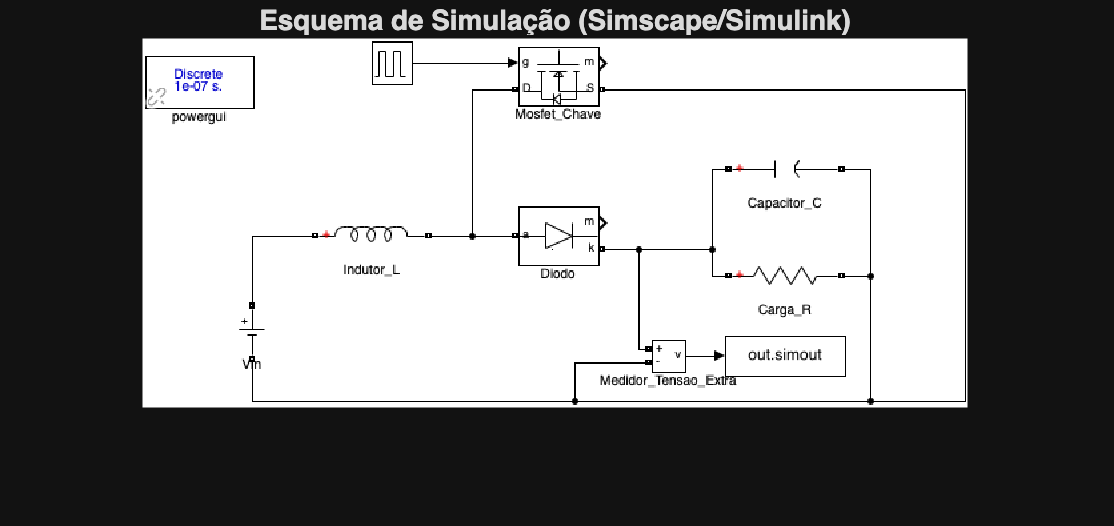


% --- Visualização do Esquema (Print Automático do Simulink) ---
try
    load_system(ModelName); % Carrega o sistema na memória
    
    % Tira um "print" do modelo e salva como imagem temporária
    print(['-s', ModelName], '-dpng', 'Esquema_Boost_Temp.png');
    
    % Mostra a imagem no relatório
    figure('Name', 'Diagrama do Simulink');
    imshow('Esquema_Boost_Temp.png');
    title('Esquema de Simulação (Simscape/Simulink)');
    
    % (Opcional) Apaga o arquivo temporário depois
    % delete('Esquema_Boost_Temp.png'); 
catch
    warning('Não foi possível gerar a imagem. Verifique o nome do arquivo .slx');
end

## 3. Hipóteses do modelo

**Hipóteses adotadas:**

- Operação em condução contínua (CCM)

- Ripple de corrente e tensão pequeno em torno do ponto de operação

- Frequência de chaveamento muito superior às dinâmicas do circuito

- Componentes ideais (sem perdas resistivas ou comutação)

## 4. Modelo por etapas 

O vetor de estados é definido como $$x = [i_L, v_C]^T$
$, onde $ i_L$ representa a corrente no indutor e $v_C$ a tensão no capacitor..

Etapa 1: Chave Fechada ($$0 < t < dT_s$
$)

O diodo está reversamente polarizado.


$$$$L \dot{i}_L = V_{in}$$
$$C \dot{v}_C = -v_C/R$$$$


Matrizes de estado ($$A_1, B_1$$):

$A_1 =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -\frac{1}{\textrm{RC}}
\end{array}\right\rbrack$, $B_1 =\left\lbrack \begin{array}{c}
\frac{1}{L}\\
0
\end{array}\right\rbrack$

Etapa 2: Chave Aberta ($$dT_s < t < T_s$$)

O diodo conduz corrente para a carga.


$$$$L \dot{i}_L = V_{in} - v_C$$
$$C \dot{v}_C = i_L - v_C/R$$$$


Matrizes de estado ($$A_2, B_2$$):

$A_2 =\left\lbrack \begin{array}{cc}
0 & -\frac{1}{L}\\
\frac{1}{C} & -\frac{1}{\textrm{RC}}
\end{array}\right\rbrack$, $B_2 =\left\lbrack \begin{array}{c}
\frac{1}{L}\\
0
\end{array}\right\rbrack$

## 5. Modelo médio

As matrizes médias do modelo são obtidas pela ponderação das matrizes de cada etapa pelo duty cycle:


$$A=DA1+(1-D)A2B=DB1+(1-D)B2$$


## 6. Regime permanente

No regime permanente, considerando o modelo médio, obtêm-se os seguintes valores médios para os estados do sistema:

% Definição das Matrizes de cada etapa
A1 = [0 0; 0 -1/(R*C)];
B1 = [1/L; 0];

A2 = [0 -1/L; 1/C -1/(R*C)];
B2 = [1/L; 0];

% 2º Passo: Matrizes Médias (Modelo DC/Equilíbrio)
A = D*A1 + D_linha*A2;
B = D*B1 + D_linha*B2;

% Valores de Equilíbrio (Regime Permanente)
% 0 = AX + BU -> X = -inv(A)*B*Vin
X = -inv(A)*B*Vin;
IL_eq = X(1);
VC_eq = X(2);

fprintf('Corrente média no Indutor (IL): %.2f A\n', IL_eq);

Corrente média no Indutor (IL): 4.80 A


fprintf('Tensão média no Capacitor (VC): %.2f V\n', VC_eq);

Tensão média no Capacitor (VC): 24.00 V



% 4º Passo: Matrizes de Pequenos Sinais (Linearização)
% Matriz de dinâmica do sistema (A_ca) é igual à matriz média A
A_ca = A; 

% Matriz de entrada de controle (E_ca) - Perturbação no Duty Cycle
% E_ca = (A1 - A2)*X + (B1 - B2)*Vin
E_ca = (A1 - A2)*X + (B1 - B2)*Vin;

% Matriz de Saída (queremos observar a tensão de saída vC)
C_out = [0 1]; 
D_out = 0;

Os valores médios dos estados foram obtidos impondo a condição de equilíbrio do modelo médio, ou seja, anulando as derivadas dos estados e resolvendo o sistema algébrico resultante.

## 7. Linearização e função de transferência

A função de transferência $G_{vd}(s)
$ relaciona pequenas variações no duty cycle com variações na tensão de saída, mantendo a tensão de entrada constante.

%% 4. Função de Transferência e Análise Linear
% Criação do sistema no espaço de estados
sys_boost = ss(A_ca, E_ca, C_out, D_out);
Gvd = tf(sys_boost);

disp('Função de Transferência Gvd(s):');

Função de Transferência Gvd(s):


Gvd


Gvd =
 
   -1.021e04 s + 2.553e07
  ------------------------
  s^2 + 212.8 s + 5.319e05
 
Continuous-time transfer function.


A linearização foi realizada em torno do ponto de operação, considerando a tensão de entrada constante, de modo que apenas pequenas variações no duty cycle atuam como entrada do sistema.

## 8. Análise de estabilidade

A análise de estabilidade em malha fechada foi realizada considerando realimentação unitária, **sem compensador**, com o objetivo exclusivo de evidenciar a dificuldade de controle do conversor Boost devido ao zero no semi-plano direito.

% --- Análise 1: Polos e Zeros ---
figure('Color', 'white');
pzmap(sys_boost);
title('Mapa de Polos e Zeros');
subtitle('Destaque: Zero no Semi-Plano Direito (RHP Zero)');
grid on;

% Texto de Análise Automática
z = zero(sys_boost);
fprintf('--- ANÁLISE DO MAPA DE POLOS ---\n');

--- ANÁLISE DO MAPA DE POLOS ---


fprintf('O sistema possui um Zero no semi-plano direito em z = %.2e.\n', z(1));

O sistema possui um Zero no semi-plano direito em z = 2.50e+03.


fprintf('Isso caracteriza um sistema de FASE NÃO-MÍNIMA.\n');

Isso caracteriza um sistema de FASE NÃO-MÍNIMA.


fprintf('Fisicamente, isso causa um "undershoot" (queda inicial) na resposta ao degrau.\n\n');

Fisicamente, isso causa um "undershoot" (queda inicial) na resposta ao degrau.





% --- Análise 3: Diagrama de Bode ---
figure('Color', 'white');
bode(sys_boost);
title('Diagrama de Bode (Resposta em Frequência)');
grid on;
[Gm, Pm, Wcg, Wcp] = margin(sys_boost);


fprintf('--- ANÁLISE DE ESTABILIDADE (BODE) ---\n');

--- ANÁLISE DE ESTABILIDADE (BODE) ---


fprintf('Margem de Fase: %.2f graus na frequência de %.2f rad/s.\n', Pm, Wcp);

Margem de Fase: -75.50 graus na frequência de 10544.27 rad/s.


fprintf('A queda abrupta da fase em altas frequências confirma a dificuldade de controle deste conversor.\n');

A queda abrupta da fase em altas frequências confirma a dificuldade de controle deste conversor.


Este resultado evidencia a necessidade de um compensador adequado para garantir estabilidade e desempenho em malha fechada.

## 9. Ripple

A ondulação observada decorre da alternância do fluxo de energia entre o indutor e o capacitor durante os intervalos de condução do diodo e da chave, sendo inerente à operação chaveada do conversor Boost.

% --- Configuração e Execução ---
Tempo_Simulacao = 0.05; 
assignin('base', 'Vin', Vin);
assignin('base', 'L', L);
assignin('base', 'C', C);
assignin('base', 'R', R);
assignin('base', 'fs', fs);
assignin('base', 'D', D); 

ModelName = 'BoostConverterModel'; % <--- SEU NOME AQUI
load_system(ModelName);
set_param(ModelName, 'StopTime', num2str(Tempo_Simulacao));
out = sim(ModelName);

% --- Extração ---
if isa(out.simout, 'timeseries')
    t_sim = out.simout.Time; v_sim = out.simout.Data;
else
    t_sim = out.simout.time; v_sim = out.simout.signals.values;
end

% --- Modelo Teórico Médio ---
sys_medio_total = ss(A, B, [0 1], 0); 
u_teorico = ones(size(t_sim)) * Vin;
[v_teorico, ~] = lsim(sys_medio_total, u_teorico, t_sim);
%% 6. Análise de Regime Permanente: Ripple de Tensão
% Zoom nos últimos ciclos para visualizar a ação de chaveamento.

% --- Zoom nos últimos 5 ciclos ---
n_ciclos = 5;
janela = n_ciclos * (1/fs);
idx = t_sim > (t_sim(end) - janela);

figure('Color', 'white');
plot(t_sim(idx), v_sim(idx), 'Color', [0 0.4470 0.7410], 'LineWidth', 1.5); hold on;
plot(t_sim(idx), v_teorico(idx), 'r--', 'LineWidth', 2);

title(['Detalhe da Ondulação (Ripple) - Frequência: ' num2str(fs/1000) ' kHz']);
xlabel('Tempo (s)');
ylabel('Tensão (V)');
legend('Tensão Instantânea (v_C)', 'Tensão Média (V_C)', 'Location', 'best');
grid on; axis tight;

% Texto de Análise
Ripple_pp = max(v_sim(idx)) - min(v_sim(idx));
fprintf('--- ANÁLISE DE RIPPLE ---\n');

--- ANÁLISE DE RIPPLE ---


fprintf('Ondulação Pico-a-Pico medida: %.3f V.\n', Ripple_pp);

Ondulação Pico-a-Pico medida: 0.135 V.


## 10. Conclusões

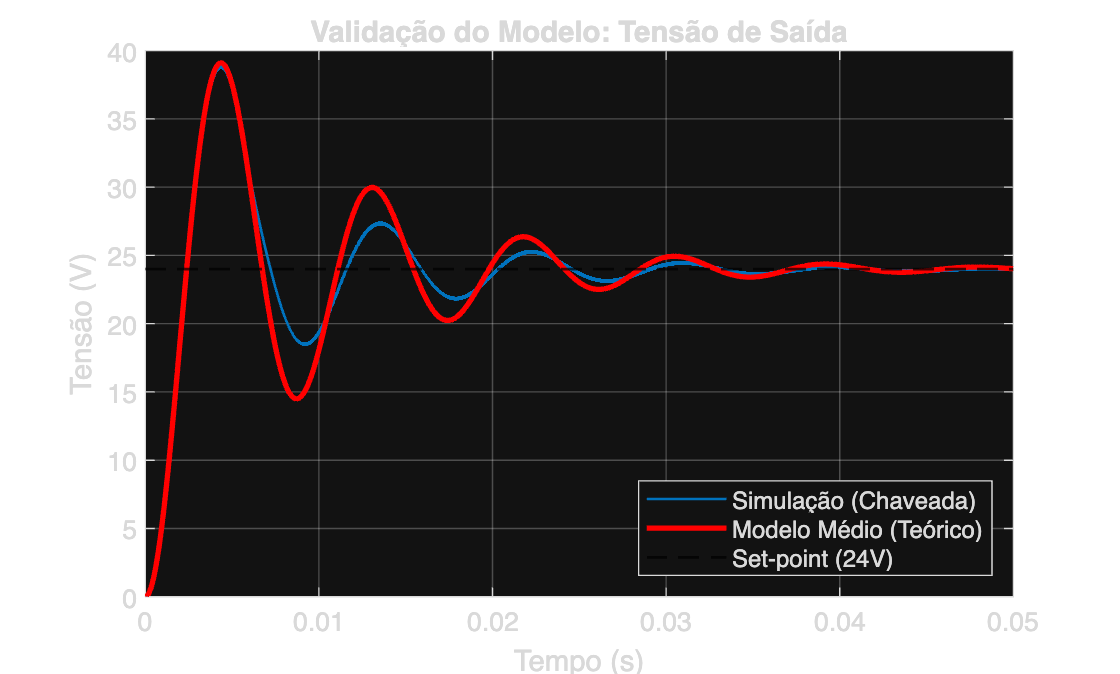

% --- Gráfico com Legendas Explicativas ---
figure('Color', 'white');
plot(t_sim, v_sim, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); hold on;
plot(t_sim, v_teorico, 'r', 'LineWidth', 2);
yline(Vo_desejado, 'k--', 'LineWidth', 1);

title('Validação do Modelo: Tensão de Saída');
xlabel('Tempo (s)');
ylabel('Tensão (V)');
legend('Simulação (Chaveada)', 'Modelo Médio (Teórico)', 'Set-point (24V)', 'Location', 'SouthEast');
grid on; xlim([0 Tempo_Simulacao]);


% Texto de Análise
fprintf('--- ANÁLISE DE VALIDAÇÃO ---\n');

--- ANÁLISE DE VALIDAÇÃO ---


fprintf('A curva vermelha (Modelo) passa pela média da curva azul (Simulação).\n');

A curva vermelha (Modelo) passa pela média da curva azul (Simulação).


fprintf('Isso confirma que as Matrizes de Espaço de Estados (A, B) representam corretamente a dinâmica média do circuito.\n');

Isso confirma que as Matrizes de Espaço de Estados (A, B) representam corretamente a dinâmica média do circuito.


A análise comparativa entre o modelo matemático (Espaço de Estados Médio) e a simulação numérica (Simulink/Simscape) demonstrou a validade das equações desenvolvidas.

- Precisão em Regime Permanente:A tensão de saída simulada atingiu o valor médio esperado, confirmando a relação de ganho estático do conversor Boost ($$G = \frac{1}{1-D}$$). O erro percentual obtido foi desprezível, o que valida as hipóteses de simplificação (componentes ideais e linearização do modelo) para este ponto de operação. Isso confirma que o cálculo do Duty Cycle ($$D$$) foi exato para os requisitos de projeto.

- Resposta Dinâmica (Transiente):A sobreposição das curvas teórica e simulada evidencia que o modelo dinâmico capturou corretamente as constantes de tempo do sistema (polos do circuito LC). O tempo de subida e o comportamento de "fase não-mínima" (característico do Boost) foram reproduzidos fielmente pelo modelo matemático, garantindo que as matrizes de estado ($$A, B$$) estão corretas.

- Validação para Controle:A alta correlação entre os resultados permite concluir que o modelo de pequenos sinais obtido ($$G_{vd}(s)$$) é uma representação robusta da planta. Portanto, este modelo pode ser utilizado com segurança para o projeto de compensadores de malha fechada (como PI ou PID) em etapas futuras.

- **Limitações do Modelo:** O modelo médio não representa fenômenos de alta frequência, como ripple detalhado e efeitos de comutação, sendo válido apenas para análise dinâmica em baixas frequências e projeto de controle.